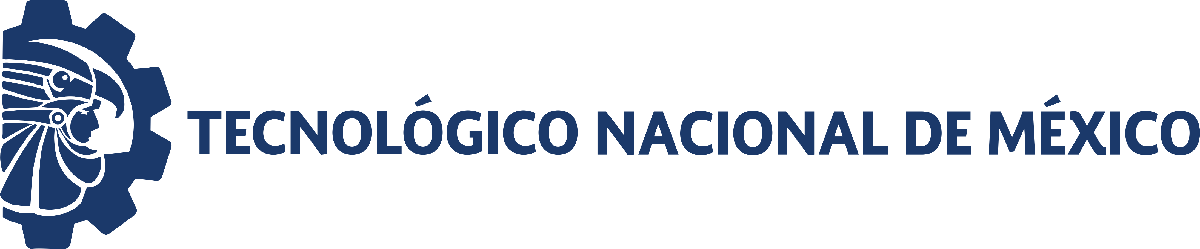                                 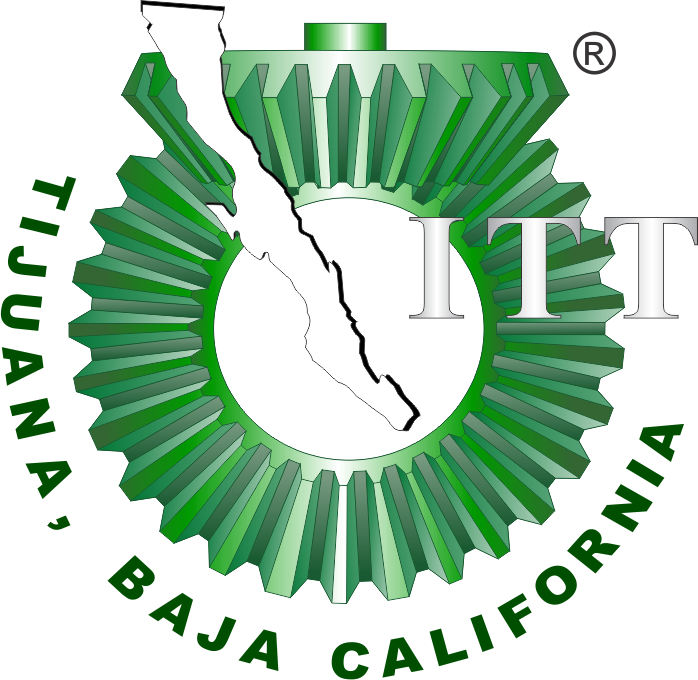

# Práctica 3: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

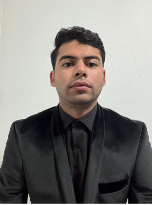

Nombre del alumno: **Perez Chavez Marco Antonio**

Número de control: **19212423**

Correo institucional: **marco.perez193@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "10";
parameters.StopTime = tend;
parameters.Solver = "ode15s";
parameters.MaxStep = "1E-3";

## Lazo Abierto

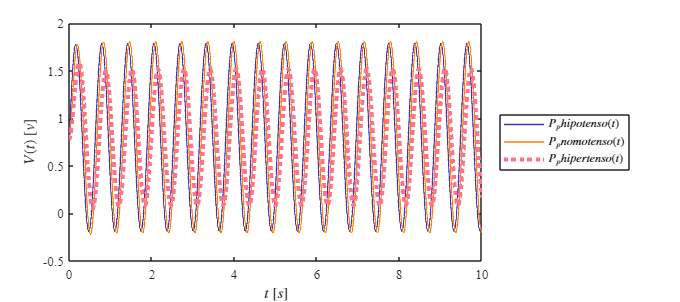

Signal = 'Lazo Abierto';
file = 'sysp3_LA';
open_system(file);
x = sim(file, parameters);
plotsignals (x.t, x.Ppx, x.Ppy, x.Ppz, Signal)

## Rendimiento del controlador Hipotenso

kP = 0.00129138922433936

kI = 106.524044065096

kD = 0

## Hipotenso

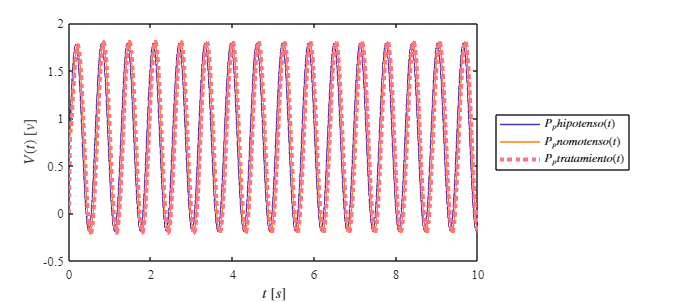

Signal = 'Controlador Hipotenso';
file = 'sysp3_LCHipo';
open_system(file);
x = sim(file, parameters);
plotsignals (x.t, x.Ppx, x.Ppy, x.Ppz, Signal)

## Rendimiento del controlador Hipertenso

kP = 0

kI = 106.772542011827

kD = 0

## Hipertenso

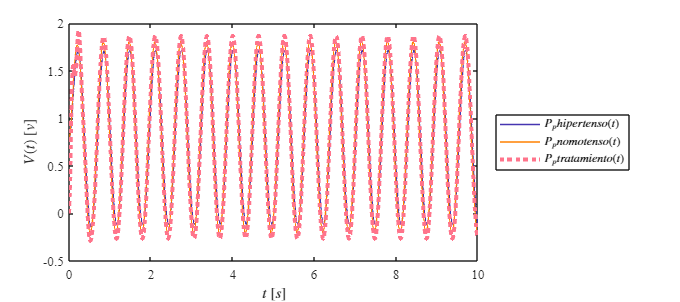

Signal = 'Controlador Hipertenso';
file = 'sysp3_LCHiper';
open_system(file);
x = sim(file, parameters);
plotsignals (x.t, x.Ppx, x.Ppy, x.Ppz, Signal)

## Funcion: Respuesta a las senales

function plotsignals(t, Ppx, Ppy, Ppz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10,'points')
    
    morado = [70/255, 53/255, 177/255];
    naranja = [1, 128/255, 0];
    rosa = [255/255, 116/255, 139/255];
    Azul = [7/255, 71/255, 153/255];

    hold on; grid off, box on;

    plot (t, Ppx, 'LineWidth', 1, 'Color', morado)
    plot (t, Ppy, 'LineWidth', 1, 'Color', naranja)
    plot (t, Ppz, ':', 'LineWidth', 3, 'Color', rosa)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$V(t)$ $[v]$', 'Interpreter', 'Latex')

   
    if Signal == "Lazo Abierto"
         L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{hipertenso}(t)$');
         set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")

    elseif Signal == "Controlador Hipotenso"
        L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")

    elseif Signal == "Controlador Hipertenso"
        L = legend('$P_{p}{hipertenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
        
    end
    %exportgraphics (gcf, [Signal,'.pdf'], 'ContentType', 'Vector')
end